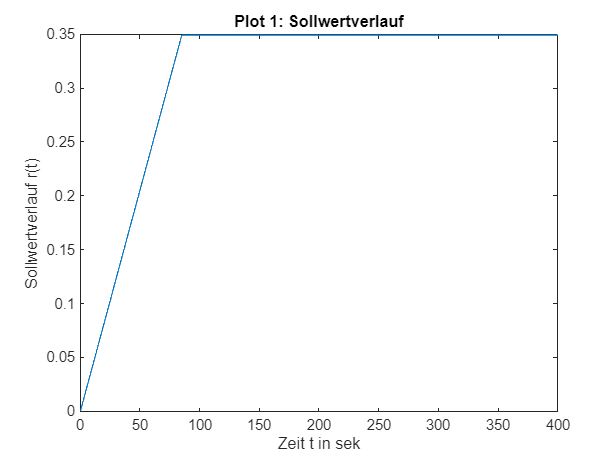

clear



% Sollwertverlauf r(t)
t = 0:0.01:400; % von 0-400 in 0.01 schritten

i = 1;
while i <= 40001

    if i <= 8501
    r(i) = (i-1).*0.01.*(deg2rad(20)./85);
    
    elseif 8501 < i & i <= 40001
    r(i) = deg2rad(20);
    end

    i = i+1;
end

plot(t,r);
title('Plot 1: Sollwertverlauf');
xlabel('Zeit t in sek');
ylabel('Sollwertverlauf r(t)');



% einfach, um die Funktionen zu testen:

s = tf('s');
J = 800;
G = 1/J/s^2;

% Regler
omega_n = 0.065;
zeta = 0.7;
kp = J*omega_n^2;
kd = 2*J*zeta*omega_n;
K = kp+kd*s/(0.1*s+1);

% calling the function to calculate transferfunctions:
[T, S, L, GS, KS] = transferfunctions(G, K);


